%making the histograms
c110 = c110(:);
clf;
hold on;
LegHandles = []; LegText = {};
[CdfF,CdfX] = ecdf(c110,'Function','cdf');
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(c110,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0 0 1],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'c110 data';
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XContinuous = linspace(XLim(1),XLim(2),100);
XIncr = max(1,floor((XLim(2)-XLim(1))/100));
XDiscrete = floor(XLim(1)):XIncr:ceil(XLim(2));
%making the error bars

normalizedelements=[0.006 0.012 0.03 0.038 0.038 0.032 0.026 0.012 0.004 0.002 0.002];
elements=500*normalizedelements;
bincenters= 87.5:5:137.5;
err=sqrt(elements)/500;
bar(bincenters, normalizedelements);

errorbar(bincenters,normalizedelements, err,'*');
%making the gaussian fit
pd1 = fitdist(c110, 'normal')

pd1 =   NormalDistribution

  Normal distribution
       mu =  106.86   [104.881, 108.839]
    sigma = 9.97271   [8.75611, 11.5851]


XGrid = XContinuous;
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'fit 1';
%making the poisson fit
pd2 = fitdist(c110, 'poisson')

pd2 =   PoissonDistribution

  Poisson distribution
    lambda = 106.86   [104.834, 108.886]


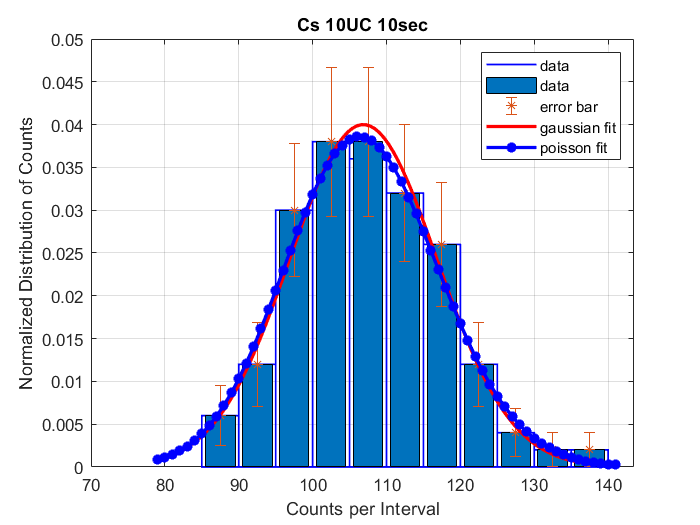

XGrid = XDiscrete;
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','*', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'fit 2';
box on;
hold off;

legend({'data','data','error bar','gaussian fit','poisson fit'})
title('Cs 10UC 10sec')
xlabel('Counts per Interval')
ylabel('Normalized Distribution of Counts')
grid on